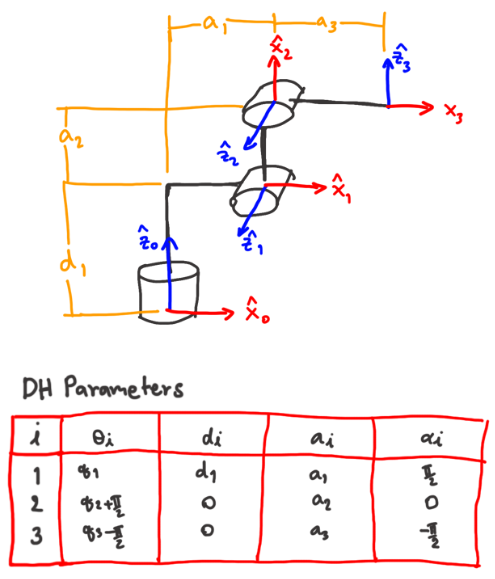

syms q1 q2 q3 pi a_1 a_2 a_3 d_1
%a_1 = 0.2;
%a_2 = 0.75;
%a_3 = 0.6;
%d_1 = 0.9;
q=[q1 q2 q3];
dh=[0 d_1 a_1 pi/2;pi/2 0 a_2 0;-pi/2 0 a_3 -pi/2];
rho=[1 1 1];
tforms = forwardKinematicsSym(q,rho,dh)

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & d_{1}+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}-a_{2}\,\sin\left(q_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & d_{1}+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}+a_{3}\,\cos\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right) \end{array}$$